slow_time = timeit(@slow_add)

slow_time =    0.503687649300000


fast_time = timeit(@fast_add)

fast_time =    0.028489349300000


slow_time / fast_time

ans =   17.679857970641681


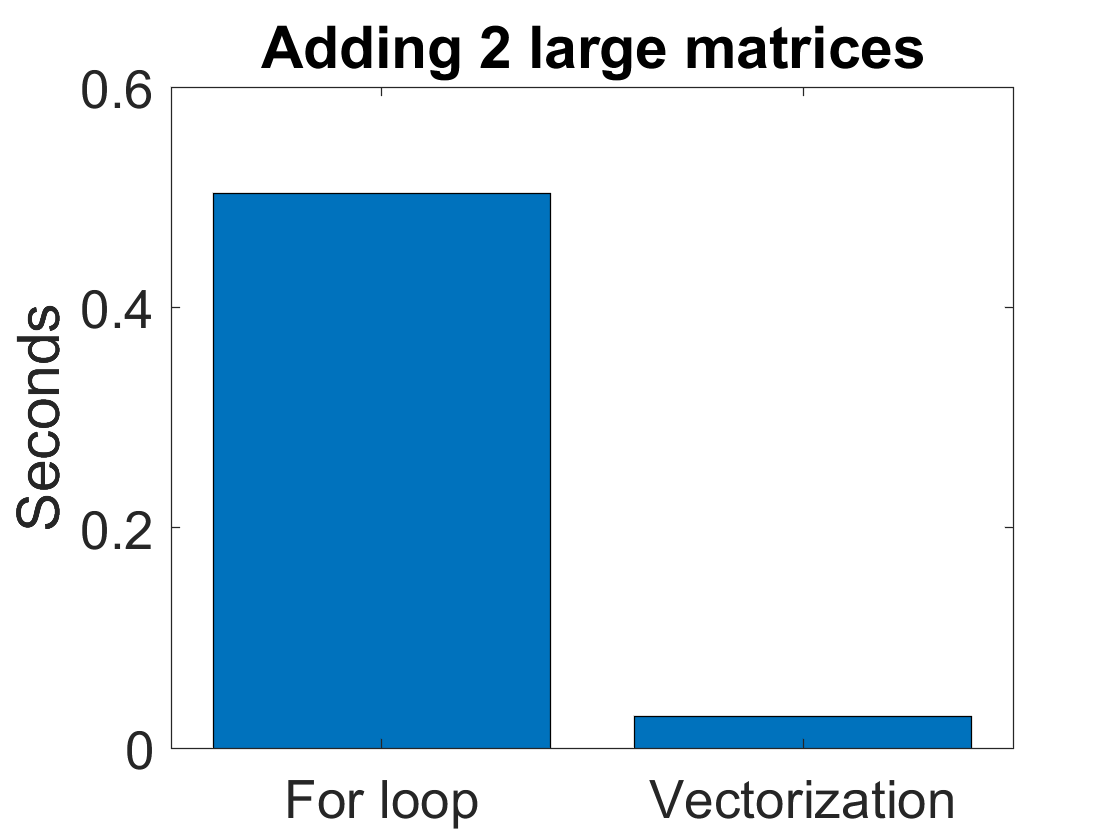

bar(categorical(["For loop", "Vectorization"]), [slow_time, fast_time])
set(gca, "FontSize", 20)
ylabel("Seconds")
title("Adding 2 large matrices")
saveas(gca, "vectorization.svg")

function slow_add()
    A = rand(1000,1000);
    B = rand(1000,1000);
    C = [];
    for i=1:1000
        for j=1:1000
            C(i,j) = A(i,j) + B(i,j);
        end
    end
end

function fast_add()
    A = rand(1000,1000);
    B = rand(1000,1000);
    A + B;
end